%[x, fs] = audioread("10sec mese.wav");
[x, fs] = audioread("moving_in_the_room.wav");
size(x)

ans =       208980           1


fs

fs = 16000

% defining parameters
x1=x(:,1);
nFft = 512;
segLen= 512;
stepsize = 256;
lenx1=length (x1);
nSegs = floor ((lenx1-stepsize)/stepsize);

% cutting signal into frames
frames=zeros(nSegs, segLen);
size(frames)

ans =    815   512



weightFrame = hamming(segLen);

for j=1:nSegs
    midPos = j*stepsize;
    startPos = midPos-stepsize+1;
    endPos = startPos+segLen-1;
    % cutting and weighting the frames
    frames(j, :)=x1(startPos:endPos); %.*weightFrame;
end

% calculate energy of frames
nrgx1=zeros(nSegs,1);
size(nrgx1)

ans =    815     1



for j=1:nSegs
    frame=frames(j,:);
    %frameSquared=frame.*frame;
    %nrgx1(j,1)=sum(frameSquared);
    
    frameAbs = abs(frame);
    %nrgx1(j,1)=sum(frameAbs);
    nrgx1(j,1)=max(frameAbs);
   
end

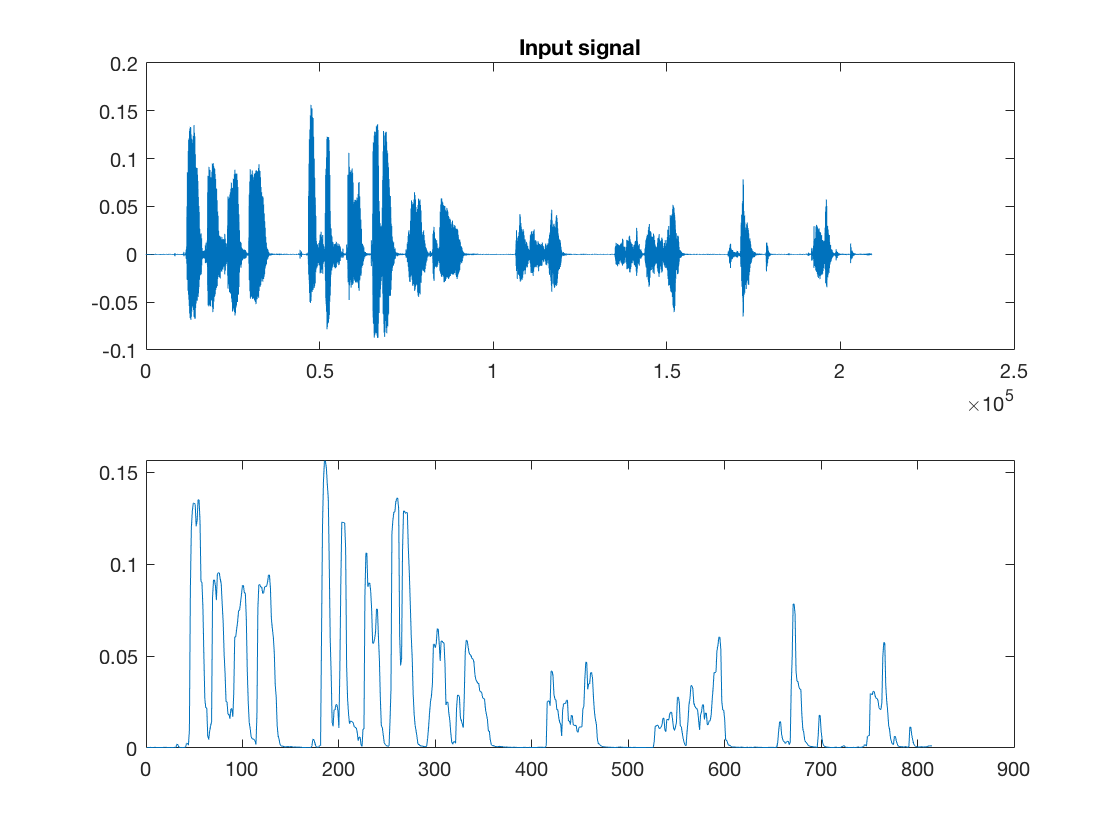

% plotting energy and weights
figure(1)
subplot(211)
plot(x1)
title('Input signal')
subplot(212)
%title('Signal energy')
plot(nrgx1)

% deriving VAD from energy
vadx1=zeros(nSegs, 1);

sorted=sort(nrgx1);
quantileHere = floor(nSegs/2)

quantileHere = 407

vadTh=sorted(quantileHere)

vadTh = 0.0060

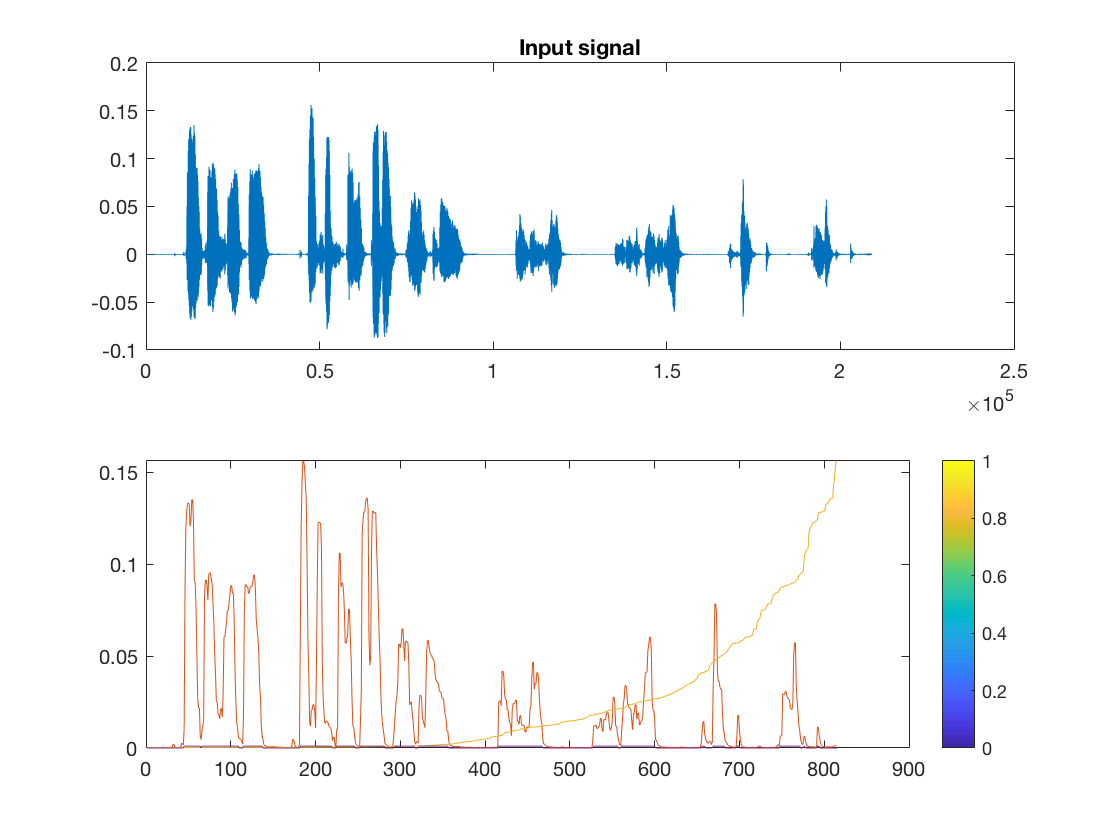

vadx1=nrgx1>vadTh;

figure(3)
hold on
plot(nrgx1)
plot(sort(nrgx1))
%plot(hist(nrgx1))
plot (vadx1/1000)
colorbar

% deriving gain from Energy and VAD
gainMin = 0.15;  % min allowed amplittude reduction: -15dB
gainMax = 6;   % max allowed amplittude reduction: +15dB
gainInit= 1;    % initial gain

targetEnergyLevel = 0.2;
minTargetEnergy = targetEnergyLevel/5;
maxTargetEnergy = targetEnergyLevel*5;

gainx1=ones(nSegs, 1);
gainx1(1)=gainInit;
for j=2:nSegs
    if  (vadx1(j-1)+vadx1(j))>0
        % frame level too small
        if nrgx1(j)<minTargetEnergy,
            boostCoeff=gainMax;
            gainx1(j)=0.9* gainx1(j-1) +0.1* boostCoeff;
            
        % frame level too high    
        elseif nrgx1(j)>maxTargetEnergy,
            % VAD segment, but high enough energy
            boostCoeff=gainMin;
            gainx1(j)=0.5* gainx1(j-1) +0.5* boostCoeff;
            
        end
    
    else %no VAD segment
        boostCoeff=0.5;
        gainx1(j)=0.9* gainx1(j-1) +0.1* boostCoeff;
        %gainx1(j) = gainx1(j-1);
    end
    % capping the amplification to +/-10 dB
    gainx1(j) = min(gainx1(j), gainMax);
    gainx1(j) = max(gainx1(j), gainMin);

end


% smooth the gain parameter 
gainx2 = gainx1;
gainx2(2:end-1) = gainx2(2:end-1) + gainx1(1:end-2);
gainx2(2:end-1) = gainx2(2:end-1) + gainx1(3:end);
gainx2(2:end-1) = gainx2(2:end-1)/3;
%gainx2(1:end-1) = gainx2(1:end-1) + gainx1(1:end-2);

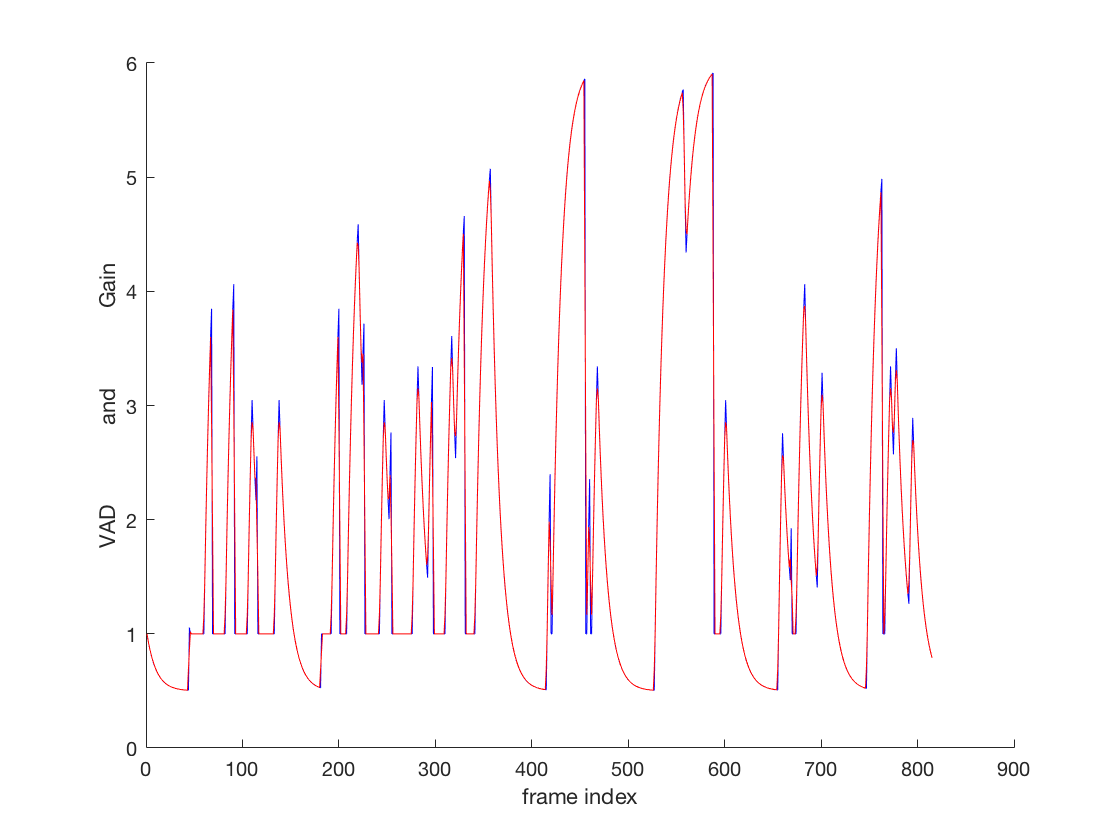

figure
clf
hold on
plot(boostCoeff)
plot(gainx1, 'b')
plot(gainx2,'r')
%plot(vadx1)
xlabel('frame index')
ylabel('VAD             and             Gain')

% weighting x1 as a matrix of frames
frames2=zeros(nSegs, segLen);

for j=1:nSegs
    frame=frames(j,:);
    frameWeighted=frame.*gainx2(j);
    frames2(j,:)= frameWeighted;
 end


% resynthesizing frames, ie.OLA
x2 = zeros(lenx1,1);

for j=1:nSegs
    midPos   = j*stepsize;
    startPos = midPos-stepsize+1;
    endPos   = startPos+segLen-1;
    
    x2(startPos:endPos)= frames2(j, :);
end

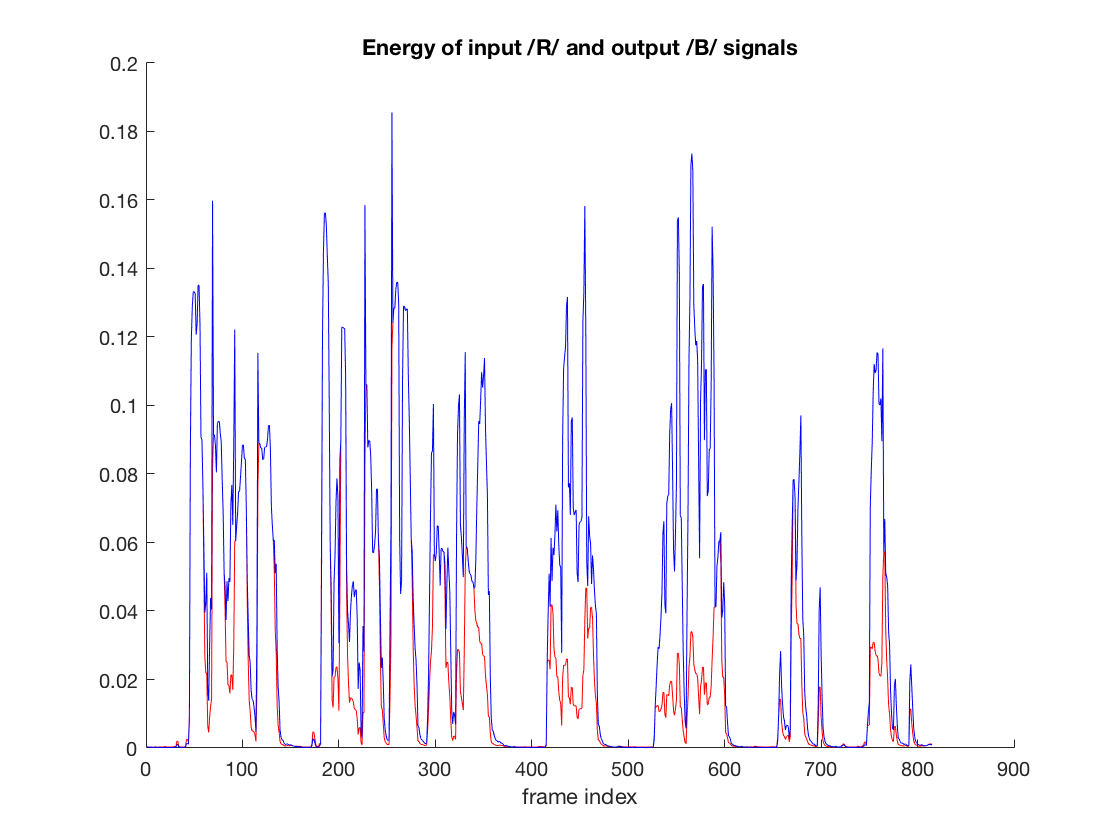

% visualizing the energy of output frames
nrgx2 = zeros (size(nrgx1));
for j=1:nSegs
    nrgx2(j)=gainx2(j)*nrgx1(j);
end

figure
clf
hold on
plot(nrgx1, 'r')
plot(nrgx2, 'b')
xlabel ('frame index')
title ("Energy of input /R/ and output " + ...
    "/B/ signals")

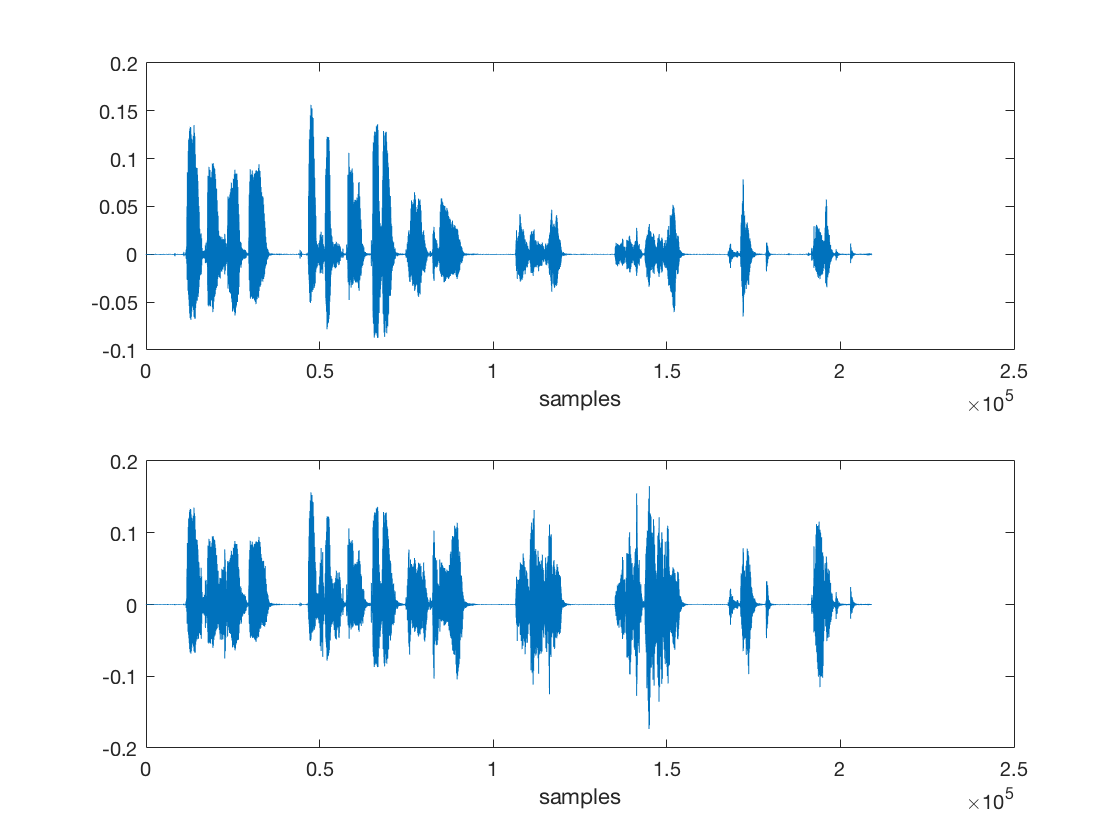

figure
subplot
subplot 211
plot(x1)
xlabel('samples')
subplot 212
plot(x2)
xlabel('samples')


% play
sound(x2, fs)
%sound(x1, fs)

% export wave
audiowrite("out.wav", x2, fs)